% import data: 4177 x 8 
[y, A] = libsvmread('datasets/abalone.txt'); 
[n,p]  = size(A);
A = full(A);
q = ceil(0.75 * n);

% split into training set and testing set
A_train = A(1:q,:);
A_test  = A(q+1:end,:);
y_train = y(1:q,:);
y_test  = y(q+1:end,:);

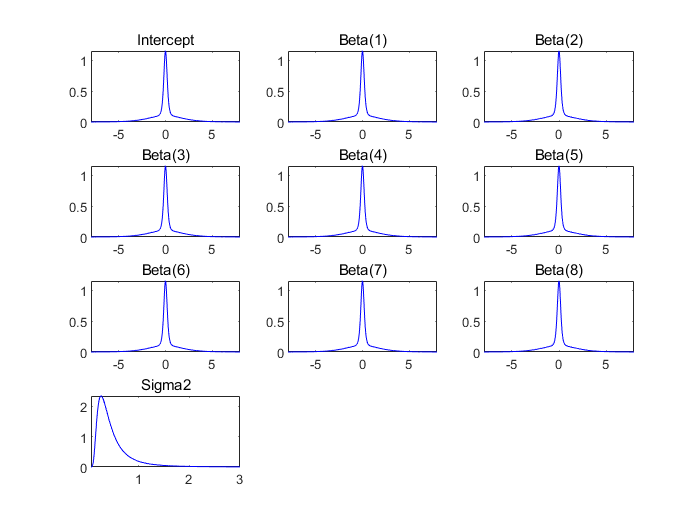

rng(42);
X_train = A_train;
X_test  = A_test; 
PriorMdl = bayeslm(p,'ModelType','mixconjugate');
plot(PriorMdl);

[PosteriorMdl,Summary] = estimate(PriorMdl,X_train,y_train);

Method: MCMC sampling with 10000 draws
Number of observations: 3133
Number of predictors:   9
 
           |   Mean      Std          CI95         Positive  Distribution  Regime 
----------------------------------------------------------------------------------
 Intercept |  11.1504  0.7529   [ 9.665, 12.615]     1.000     Empirical    1     
 Beta(1)   |  -0.3841  0.0543   [-0.491, -0.276]     0.000     Empirical   0.1082 
 Beta(2)   |  -0.3176  0.5774   [-1.490,  0.788]     0.289     Empirical   0.1521 
 Beta(3)   |   3.6435  0.6186   [ 2.447,  4.904]     1.000     Empirical   0.9976 
 Beta(4)   |   5.0158  0.9121   [ 3.225,  6.797]     1.000     Empirical   0.9997 
 Beta(5)   |  12.6050  1.1894   [10.262, 14.939]     1.000     Empirical    1     
 Beta(6)   | -14.6379  0.6986  [-16.023, -13.252]    0.000     Empirical    1     
 Beta(7)   |  -3.8508  0.5674   [-4.972, -2.737]     0.000     Empirical   0.9987 
 Beta(8)   |   4.6363  0.6493   [ 3.377,  5.915]     1.000     Empirical  

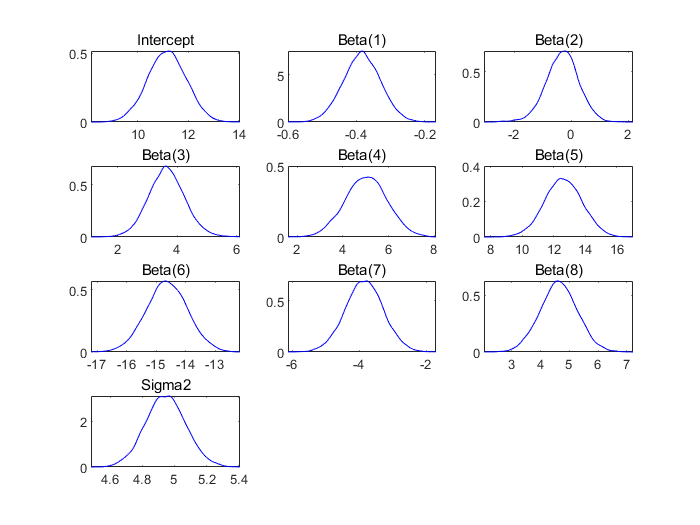

plot(PosteriorMdl);

% prediction
pred_train = forecast(PosteriorMdl,X_train);
fmse_train = sqrt(mean((y_train - pred_train).^2));
pred_test = forecast(PosteriorMdl,X_test);
fmse_test = sqrt(mean((y_test - pred_test).^2));
fprintf('train: %.3f, test: %.3f\n',fmse_train,fmse_test);

train: 2.221, test: 2.130


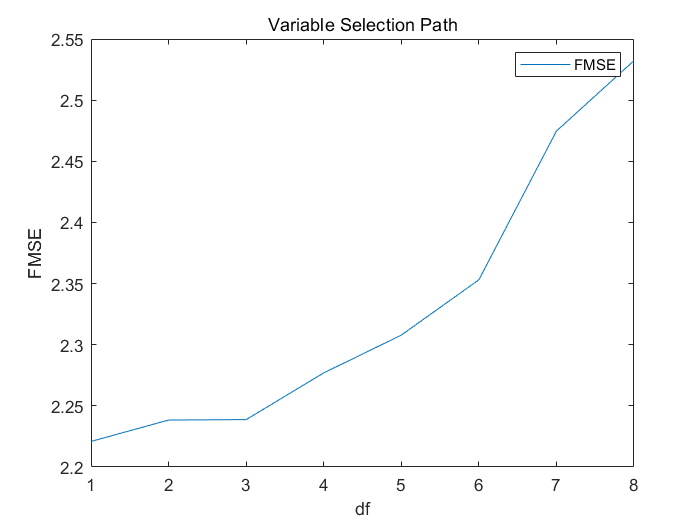

fmse = zeros(8,1);
for i = 1:8
    prior = bayeslm(p-i+1,'ModelType','mixconjugate');
    post  = estimate(prior,A_train(:,i:end),y_train,'Display',false);
    pred = forecast(post,A_train(:,i:end));
    fmse(i) = sqrt(mean((y_train - pred).^2));
end
figure;
plot(fmse);
xlabel('df');
ylabel('FMSE');
legend('FMSE');
title('Variable Selection Path');

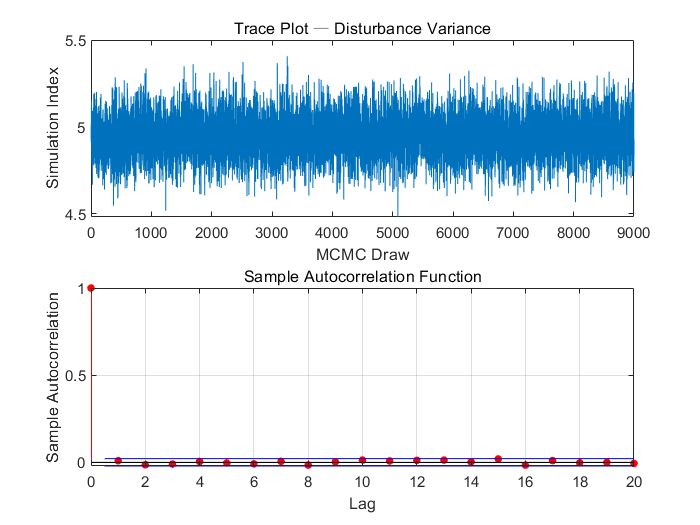

figure;
subplot(2,1,1);
plot(PosteriorMdl.Sigma2Draws(1001:end));
title(['Trace Plot ' char(8212) ' Disturbance Variance']);
xlabel('MCMC Draw');
ylabel('Simulation Index');
subplot(2,1,2);
autocorr(PosteriorMdl.Sigma2Draws(1001:end));

% effective sample size 
fprintf("ESS: %d\n",ESS(PosteriorMdl.Sigma2Draws(1001:end))');

ESS: 8.840166e+03


% we can use the draws for prediction 
beta = PosteriorMdl.BetaDraws(:,1001:end);
sigma2 = PosteriorMdl.Sigma2Draws(1001:end);
[m,~] = size(A_train);
X = [ones(m,1) , A_train]; 
y_draw = zeros(9000,m);
for i = 1:9000
    y_draw(i,:) = normrnd(X * beta(:,i), sigma2(i));
end
pred_train = mean(y_draw)';
fmse_train = sqrt(mean((y_train - pred_train).^2));

[m,~] = size(A_test);
X = [ones(m,1) , A_test]; 
y_draw = zeros(9000,m);
for i = 1:9000
    y_draw(i,:) = normrnd(X * beta(:,i), sigma2(i));
end
pred_test = mean(y_draw)';
fmse_test = sqrt(mean((y_test - pred_test).^2));
fprintf('train: %.3f, test: %.3f\n',fmse_train, fmse_test);

train: 2.222, test: 2.130


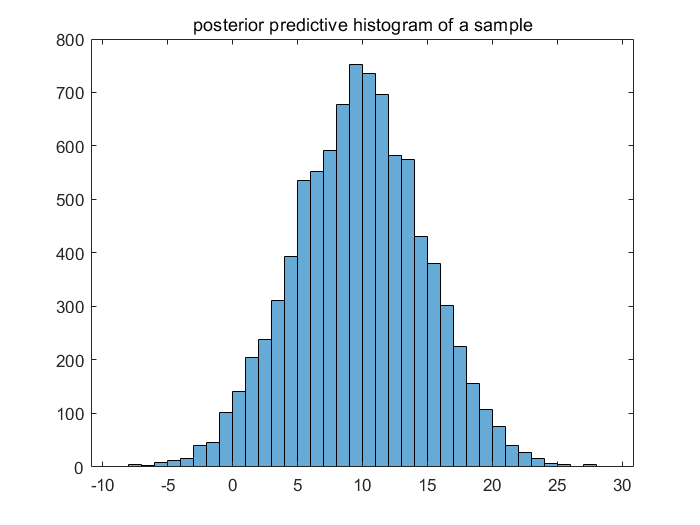


% plot the posterior predictive distribution
demo = y_draw(:,1);
figure;
histogram(demo);
title('posterior predictive histogram of a sample');